# Filtrado con frequencia de muestreo

## Radian domain

Filtro en la frecuencia de $-\pi \;$a $\pi$ con el filtro hasta $|\frac{\pi }{2}|$

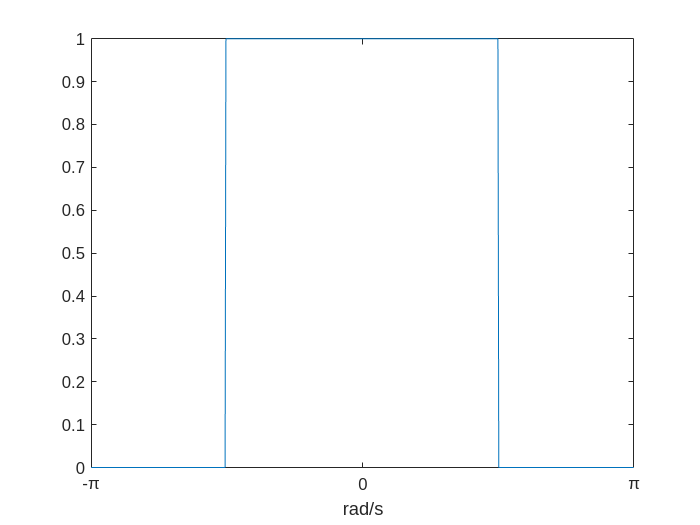

bound =[-pi,pi];
space = bound(1):1/100:bound(2);
rad_space = zeros(1,length(space));
rad_space(int32(length(space)/4):int32(3*length(space)/4)) = 1;
plot(space,rad_space)
xlim([-pi pi])
xticks([-pi 0 pi 2*pi 3*pi])
xticklabels({'-\pi','0','\pi'})
xlabel('rad/s')

## Frequency domain

Multiplicamos el eje por $2\pi$. Esto para hacer la conversion de $\frac{\textrm{rad}}{s}$ a $\textrm{Hz}=\frac{1}{s}$

$\omega =2\pi f$ , $f=\frac{\omega }{2\pi }$

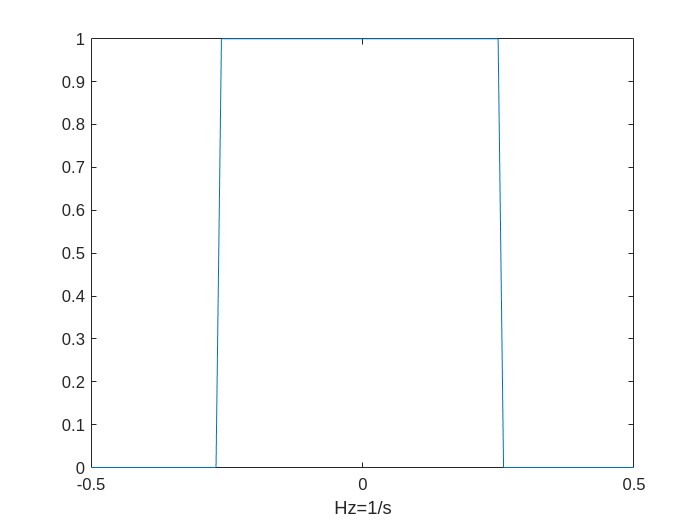

bound_freq = bound./(2*pi);
space_freq = bound_freq(1):1/100:bound_freq(2);
freq_space = zeros(1,length(space_freq));
freq_space(int32(length(space_freq)/4):int32(3*length(space_freq)/4)) = 1;
plot(space_freq,freq_space)
xlabel('Hz=1/s')

## Sampling Frequency domain

En este ultimo paso multiplicamos por la frequencia de muestreo $F_S$ para obtner el **maximo espacio libre de alias .**

Det tal forma que la venta queda de $\left\lbrack -\frac{F_s }{2},\frac{F_s }{2}\right\rbrack$

Sin embargo estamos buscando tener un filtro basabajas a $4\textrm{Khz}$ . Para ello tenemos que preguntarnos que valor tendria que ser la frequencia de muestro. 

Si $4\textrm{Khz}\;$representa .25 de .5 como se puede apreciar en la grafica de arriba, esto quiere decir que el limite de observacion tiene que $8\textrm{Khz}=\frac{F_s }{2}$

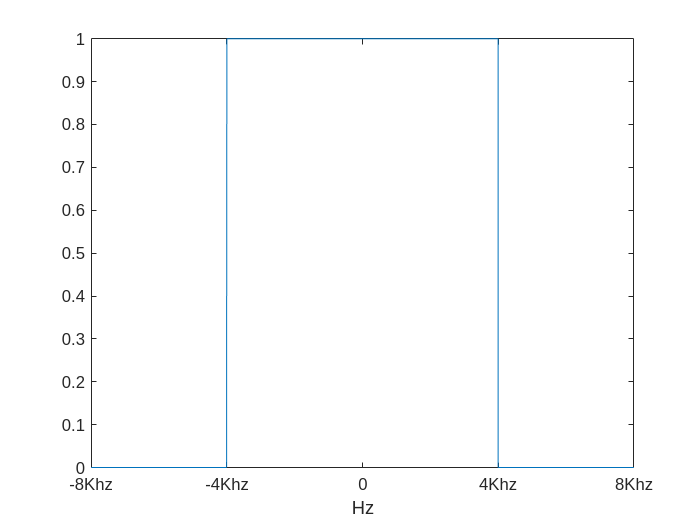

Fs=16000;
bound_fs = bound_freq.*(Fs);
space_fs = bound_fs(1):1/100:bound_fs(2);
fs_space = zeros(1,length(space_fs));
fs_space(int32(length(space_fs)/4):int32(3*length(space_fs)/4)) = 1;
plot(space_fs,fs_space)
xlabel('Hz')
xticks([-8000 -4000 0 4000 8000])
xticklabels({'-8Khz','-4Khz','0','4Khz','8Khz'})

## Resolucion Frequencial

### Filtro pasabanda

Recordar que la frequencia de muestreo nos ayuda a definir nuestra ventana de observacion. 

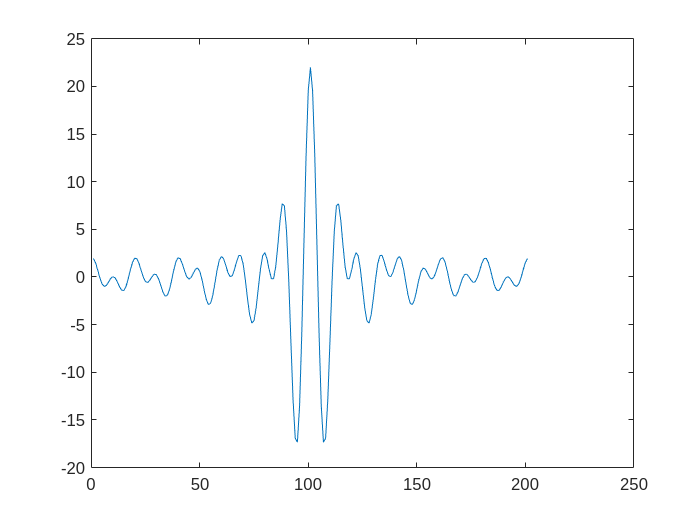

Fs = 100; % frequencia de muestreo
freq = -(Fs/2):1/2:(Fs/2); % Resolucion de medio hertz
filter_f = zeros(1,length(freq));
filter_f(find(freq==5):find(freq==10)) = 1;
filter_f(find(freq==-10):find(freq==-5)) = 1;
filter_t = real(ttof(filter_f));
plot(filter_t);

Una vez obtenido buscaremos quedarnos con los coeficientes del centro. En este caso 51 coeficnietes de un filtro pasabanda de a 5 a 10 hz si la frecuencia de muestreo es de 100 $\frac{\textrm{samples}}{\sec }$ 

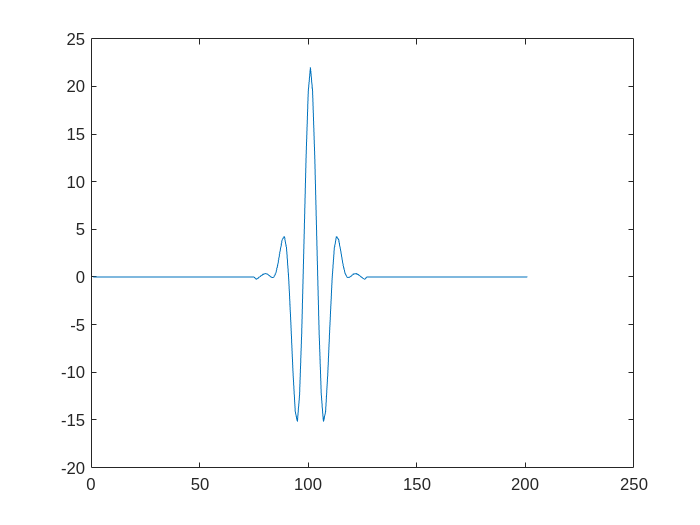

% La ventana depende totalmente de la frequencia de muestreo. 
window = zeros(1,length(freq));
filer_len = 51;
filter_half = (filer_len-1)/2;
midd = int32(length(freq)/2);
window(midd-filter_half:midd+filter_half) = hamming(filer_len);
%limiting filter to square 
final_filter = filter_t.*window;
plot(final_filter);

Veamos ahora como se comporta en la frecuencia

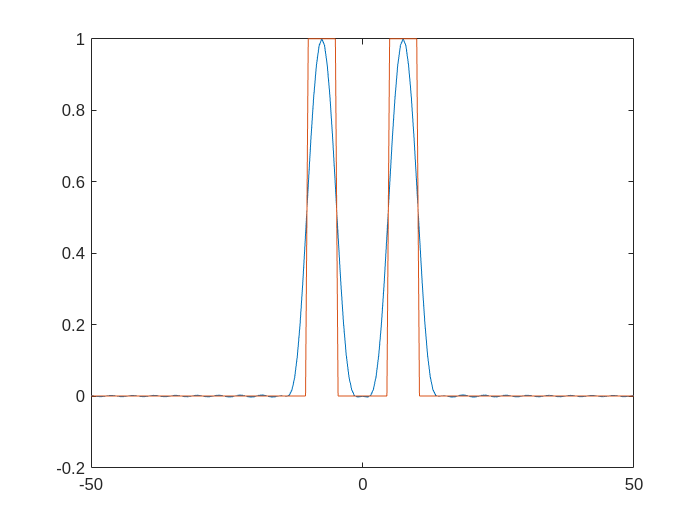

%hold on;
%filtro normalizado por eso el max
plot(freq,real(ttof(final_filter))/max(real(ttof(final_filter))))
hold on;
plot(freq,filter_f);
hold off;